%Generate 100 years of rainfall (at daily timescale) 
% with the parameters (mean daily rainfall depth α and rainfall frequency λ) 
% estimated from the observed precipitation.

%The resultingtime series should have one value for each day with mm/day as unit.

clear

load P.txt

N_years = length(P)/(365*24) ;


## 1. Upscale statistics from hourly to daily


P_daily = zeros(365*N_years, 1);
for i = 1:length(P)/24
    P_daily(i) = sum(P(i*24 - 23 : 24*i)) ;  % [mm/day]
end


day_month=[31 28 31 30 31 30 31 31 30 31 30 31];
month_end=cumsum(day_month);      
month_start=month_end-day_month+1;      

P_daily = reshape(P_daily,365,N_years); 

## 2. Evaluate the parameters alpha (mean precipitation intensity) and λ (frequency of rain- fall events). Account for seasonality by computing different values of the parameters for each month.

monthly statistics of the 6 years of precipitation series

%rainy_days = sum(P_daily ~= 0) ; 
%no_rain_days = sum(P_daily == 0) ;

% initialisation

rainy_days_monthly = zeros(12,1);
no_rain_days_monthly = zeros(12,1);

lambda = zeros(12,1);
alpha = zeros(12,1);

m_mean = zeros(12,1);
m_std = zeros(12,1);


for i = 1:12
    temp = P_daily(month_start(i):month_end(i),:) ; % all daily precipitations for month i
    temp = temp(:) ;

    %rainy_days_monthly(i) = sum(sum(temp ~= 0))/N_years ; 
    rainy_days_monthly(i) = nnz(temp);
    no_rain_days_monthly(i) = sum(sum(temp == 0))/N_years ;

    lambda(i) =  rainy_days_monthly(i)/ length(temp) ; % nb. of rainy days / nb. of days
    alpha(i) = sum(temp)/rainy_days_monthly(i) ; % sum of rainfall / nb. of rainy days
    
    % monthly mean
    m_mean(i) = mean(temp);
    % montlhy standard deviation
    m_std(i) = std(temp) ;
end



## 3. Generate 100 years of rainfall


rainfall = zeros(1, 36500) ;

%r= [];
x = rand(size(rainfall));

for i = 1:365*100
    % find the current month 
    hour = i*24-1; % hour = 1 corresponds to 00:00
    day = floor((hour - floor(hour/8760)*8760) / 24) + 1 ; 
    month = find(day <= month_end, 1, "first") ;
    
    
    %r = [r rand(1,1)];
    if rand(1, 1) < lambda(month)
        rainfall(i) = -log( 1 - rand(1,1))./ (1/alpha(month)) ;
    else
        rainfall(i) = 0 ;
    end
end
rainfall = rainfall';

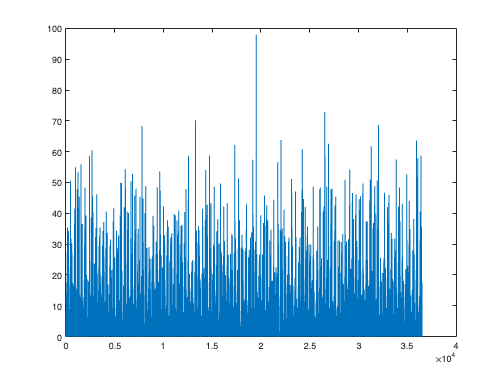



figure
plot(rainfall)

##  new statistics

P_daily = reshape(rainfall,365,100); 
rainy_days_monthly_2 = zeros(12,1);
no_rain_days_monthly_2 = zeros(12,1);
lambda_2 = zeros(12,1);
alpha_2 = zeros(12,1);
m_mean_2 = zeros(12,1);
m_std_2 = zeros(12,1);

for i = 1:12
    temp = P_daily(month_start(i):month_end(i),:) ; % all daily precipitations for month i
    temp = temp(:) ;

    %rainy_days_monthly(i) = sum(sum(temp ~= 0))/N_years ; 
    rainy_days_monthly_2(i) = nnz(temp);
    no_rain_days_monthly_2(i) = sum(sum(temp == 0))/N_years ;

    lambda_2(i) =  rainy_days_monthly_2(i)/ length(temp) ; % nb. of rainy days / nb. of days
    alpha_2(i) = sum(temp)/rainy_days_monthly_2(i) ; % sum of rainfall / nb. of rainy days
    
    % monthly mean
    m_mean_2(i) = mean(temp);
    % montlhy standard deviation
    m_std_2(i) = std(temp) ;
end


## 4. down-scale the generated daily rainfall to hourly rainfall

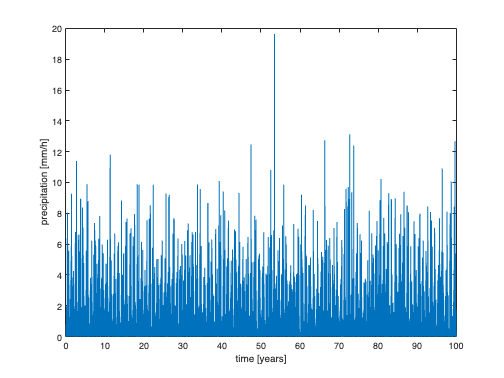

P_HOURLY = downscaling(rainfall);
save('P_hourly.mat','P_HOURLY');

plot((1:length(P_HOURLY))/(24*365),P_HOURLY)
ylabel("precipitation [mm/h]")
xlabel("time [years]")



max(P_HOURLY)

ans = 19.6293

min(P_HOURLY)

ans = 0